# File Name: MATLAB_Basic_01_given.m %%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clear; close all;

## Create first point clouds.

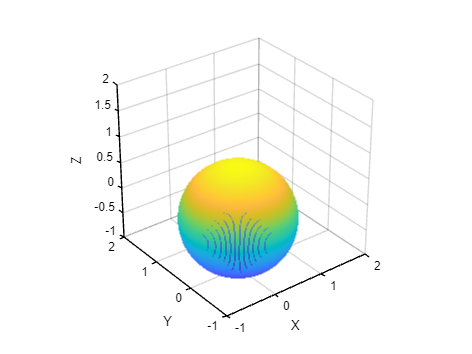

numFaces = 300;
[x1,y1,z1] = sphere(numFaces);

loc1 = [x1(:), y1(:), z1(:)];

%%%%%%%%%% TODO %%%%%%%%%%
% Create point cloud A.
ptCloudA = pointCloud(loc1);
pcshow(ptCloudA);
xlabel('X');
ylabel('Y');
zlabel('Z');
xlim([-1, 2]);
ylim([-1, 2]);
zlim([-1, 2]);
set(gcf,'color','w');
set(gca,'color','w');
set(gca, 'XColor', [0. 0. 0.], 'YColor', [0. 0. 0.], 'ZColor', [0. 0. 0.])

## Create second point clouds.

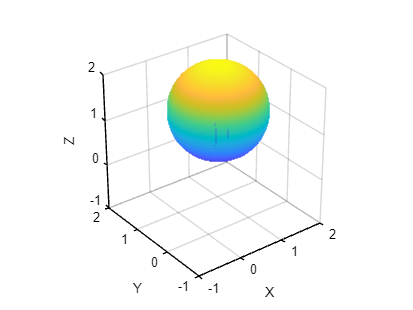

loc2 = loc1 + 1;
ptCloudB = pointCloud(loc2);
figure

%%%%%%%%%% TODO %%%%%%%%%%
% Create point cloud B.
pcshow(ptCloudB)
xlim([-1, 2]);
ylim([-1, 2]);
zlim([-1, 2]);
xlabel('X');
ylabel('Y');
zlabel('Z');
set(gcf,'color','w');
set(gca,'color','w');
set(gca, 'XColor', [0. 0. 0.], 'YColor', [0. 0. 0.], 'ZColor', [0. 0. 0.])

## Merge the two point clouds.

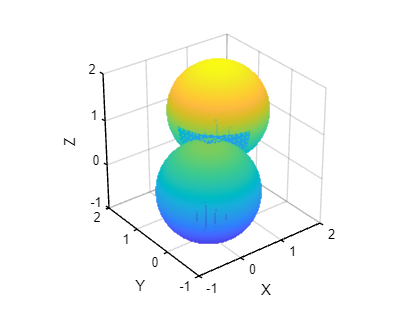

%%%%%%%%%% TODO %%%%%%%%%%%
% Merge point cloud A and B.
ptCloud = pcmerge(ptCloudA, ptCloudB, 0.1);
figure
pcshow(ptCloud);
xlim([-1, 2]);
ylim([-1, 2]);
zlim([-1, 2]);
xlabel('X');
ylabel('Y');
zlabel('Z');
set(gcf,'color','w');
set(gca,'color','w');
set(gca, 'XColor', [0. 0. 0.], 'YColor', [0. 0. 0.], 'ZColor', [0. 0. 0.])